%% Initialisierung
clear; % Löscht Variablen im Workspace
clc; % Löscht die Befehlszeile

% ---- Tiefpass-Teil ----
% Gegebene Werte für Tiefpass       R nach E12, C nach E6
R1_Tiefpass = 15e3; % Ohm
R2_Tiefpass = 82e3; % Ohm
R3_Tiefpass = 33e3; % Ohm
C1_Tiefpass = 680e-12; % Farad
C2_Tiefpass = 470e-12; % Farad
C3_Tiefpass = 6.8e-12; % Farad
zeta_Tiefpass = 0.161586; % Angenommener Wert für das Dämpfungsverhältnis @ Gainripple = 3dB = *0.5
                            % 20^(0.5/10)-1 = 0.161586

% Symbolische Variable s definieren
s = tf('s');

% Cut-off Frequenzen für Tiefpass berechnen
fc1_Tiefpass = 1 / (2 * pi * R1_Tiefpass * C1_Tiefpass);
fc2_Tiefpass = 1 / (2 * pi * sqrt(R2_Tiefpass * R3_Tiefpass * C2_Tiefpass * C3_Tiefpass));
fosz_Tiefpass = 53758;

disp(['fc1_Tiefpass: ', num2str(fc1_Tiefpass), ' Hz']);

fc1_Tiefpass: 15603.4258 Hz


disp(['fc2_Tiefpass: ', num2str(fc2_Tiefpass), ' Hz']);

fc2_Tiefpass: 54119.3847 Hz



fc1TP_rad = 2*pi*fc1_Tiefpass;
fc2TP_rad = 2*pi*fc2_Tiefpass;
foszTP_rad = 2*pi*fosz_Tiefpass;

% Tiefpass-Übertragungsfunktionen definieren
% RC Tiefpass
T_RC_Tiefpass = (2 * pi * fc1_Tiefpass) / (s + (2 * pi * fc1_Tiefpass));
% Sallen-Key Tiefpass  ohne cheby-Verhalten
T_SK_Tiefpass = (2 * pi * fc2_Tiefpass)^2 / (s^2 + s * (2 * pi * fc2_Tiefpass) * 2 * zeta_Tiefpass + (2 * pi * fc2_Tiefpass)^2);

% Gesamtübertragungsfunktion für Tiefpass berechnen
Gesamt_Tiefpass = T_RC_Tiefpass * T_SK_Tiefpass;

% ---- Hochpass-Teil ----
% Gegebene Werte für Hochpass       R nach E12, C nach E6
R1_Hochpass = 4.7e3; % Ohm
R2_Hochpass = 5.6e3; % Ohm
R3_Hochpass = 470e3; % Ohm
C1_Hochpass = 220e-12; % Farad
C2_Hochpass = 68e-12; % Farad
C3_Hochpass = 68e-12; % Farad
zeta_Hochpass = 0.161586; % Angenommener Wert für das Dämpfungsverhältnis @ Gainripple = 3dB

% Cut-off Frequenzen für Hochpass berechnen
fc1_Hochpass = 1 / (2 * pi * R1_Hochpass * C1_Hochpass);
fc2_Hochpass = 1 / (2 * pi * sqrt(R2_Hochpass * R3_Hochpass * C2_Hochpass * C3_Hochpass));
fosz_Hochpass = 49866;

disp(['fc1_Hochpass: ', num2str(fc1_Hochpass), ' Hz']);

fc1_Hochpass: 153921.6084 Hz


disp(['fc2_Hochpass: ', num2str(fc2_Hochpass), ' Hz']);

fc2_Hochpass: 45621.3651 Hz



fc1HP_rad = 2*pi*fc1_Hochpass;
fc2HP_rad = 2*pi*fc2_Hochpass;
foszHP_rad = 2*pi*fosz_Hochpass;

% Hochpass-Übertragungsfunktionen definieren
% RC Hochpass
H_RC_Hochpass = s / (s + 2*pi*fc1_Hochpass);
% Sallen-Key Hochpass ohne cheby-Verhalten
H_SK_Hochpass = s^2 / (s^2 + s*(2*pi*fc2_Hochpass)*2*zeta_Hochpass + (2*pi*fc2_Hochpass)^2);

% Gesamtübertragungsfunktion für Hochpass berechnen
Gesamt_Hochpass = H_RC_Hochpass * H_SK_Hochpass;

% ---- Bandpass-Teil ----
% Berechnung der Gesamtübertragungsfunktion für den Bandpass
Gesamt_Bandpass = Gesamt_Tiefpass * Gesamt_Hochpass;

% Übertragungsfunktionen anzeigen
disp('Gesamtübertragungsfunktion Bandpass:');

Gesamtübertragungsfunktion Bandpass:


disp(Gesamt_Bandpass);

  tf with properties:

       Numerator: {[0 0 0 1.1336e+16 0 0 0]}
     Denominator: {[1 1.2677e+06 5.1852e+11 2.6047e+17 5.0247e+22 1.1992e+28 9.0083e+32]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



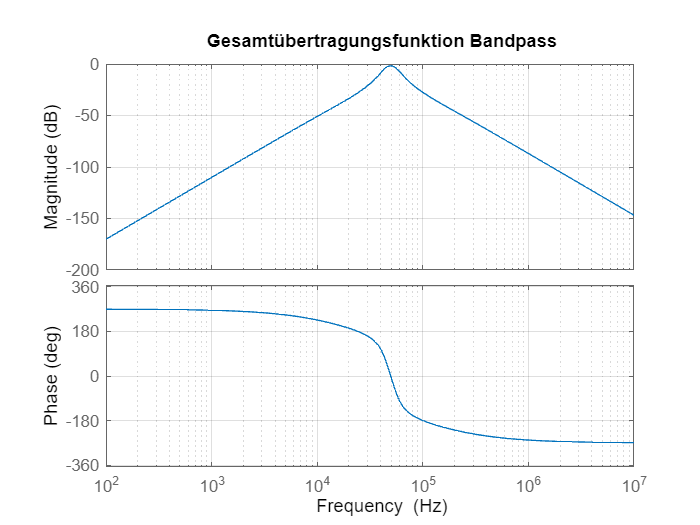


% Bode-Diagramm für Bandpass zeichnen
figure;
BodeDgrBPges = bodeplot(Gesamt_Bandpass);
title('Gesamtübertragungsfunktion Bandpass');
opt = getoptions(BodeDgrBPges);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrBPges,opt);

Bode TP 1ste Ordnung

[Ziel_Coeff_Za_TP1,Ziel_Coeff_Ne_TP1] = cheby1(1,3,fc1TP_rad,'low', 's');
Ziel_Coeff_Ne_TP1 = Ziel_Coeff_Ne_TP1 / Ziel_Coeff_Za_TP1(2);
Ziel_Coeff_Za_TP1 = Ziel_Coeff_Za_TP1 / Ziel_Coeff_Za_TP1(2);

f_von_p_TP1 = tf(Ziel_Coeff_Za_TP1,Ziel_Coeff_Ne_TP1)

f_von_p_TP1 =
 
         1
  ---------------
  1.018e-05 s + 1
 
Continuous-time transfer function.



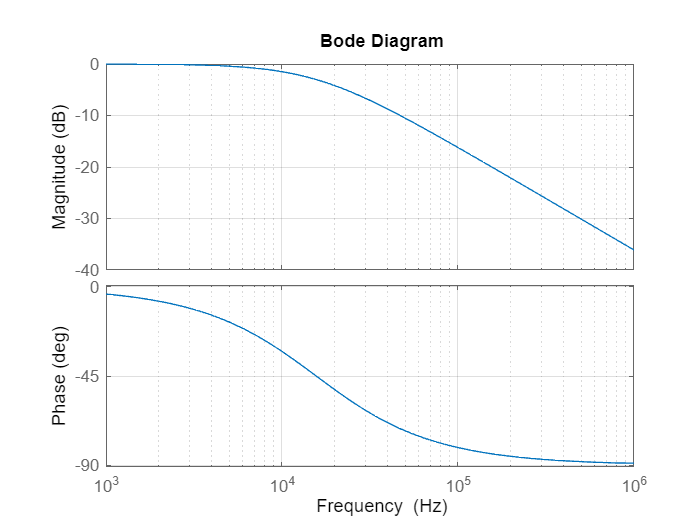


BodeDgrTP1 = bodeplot(f_von_p_TP1); 
opt = getoptions(BodeDgrTP1);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP1,opt);

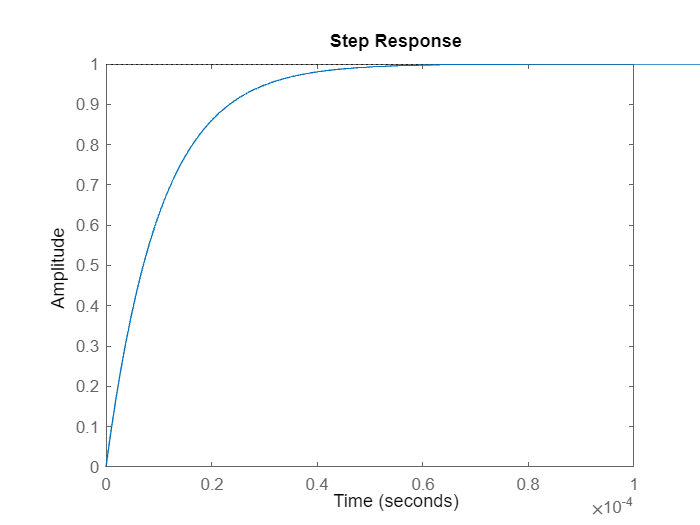


step(f_von_p_TP1);

Bode TP 2er Ordnung

[Ziel_Coeff_Za_TP2,Ziel_Coeff_Ne_TP2] = cheby1(2,3,fc2TP_rad,'low', 's');
Ziel_Coeff_Ne_TP2 = Ziel_Coeff_Ne_TP2 / Ziel_Coeff_Ne_TP2(3);
Ziel_Coeff_Za_TP2 = Ziel_Coeff_Za_TP2 / Ziel_Coeff_Za_TP2(3);

f_von_p_TP2 = tf(Ziel_Coeff_Za_TP2,Ziel_Coeff_Ne_TP2)

f_von_p_TP2 =
 
                 1
  -------------------------------
  1.222e-11 s^2 + 2.679e-06 s + 1
 
Continuous-time transfer function.



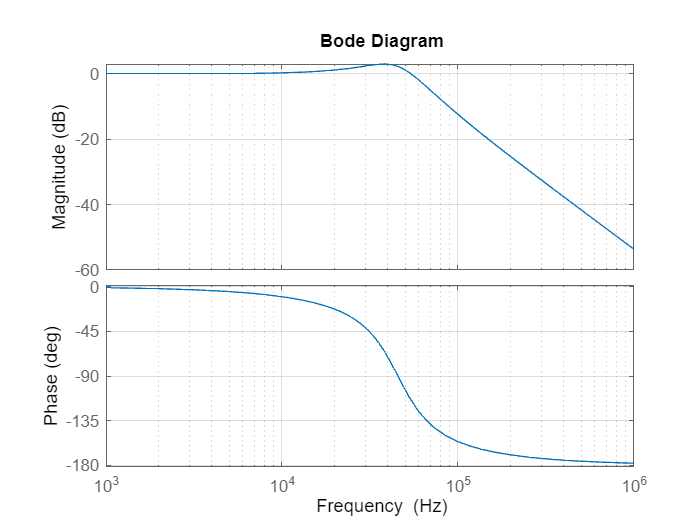


BodeDgrTP2 = bodeplot(f_von_p_TP2); 
opt = getoptions(BodeDgrTP2);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP2,opt);

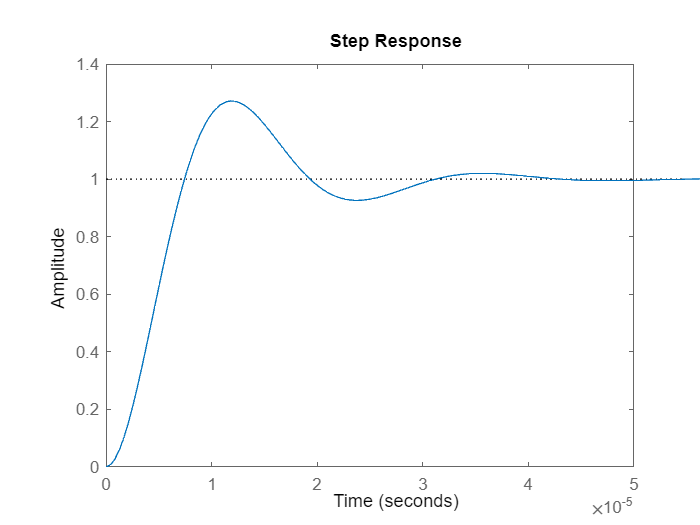


step(f_von_p_TP2);

TP3

[Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3] = cheby1(3,3,foszTP_rad,'low', 's');
Ziel_Coeff_Ne_TP3 = Ziel_Coeff_Ne_TP3 / Ziel_Coeff_Za_TP3(4);
Ziel_Coeff_Za_TP3 = Ziel_Coeff_Za_TP3 / Ziel_Coeff_Za_TP3(4);

f_von_p_TP3 = tf(Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3)

f_von_p_TP3 =
 
                         1
  -----------------------------------------------
  1.036e-16 s^3 + 2.089e-11 s^2 + 1.097e-05 s + 1
 
Continuous-time transfer function.



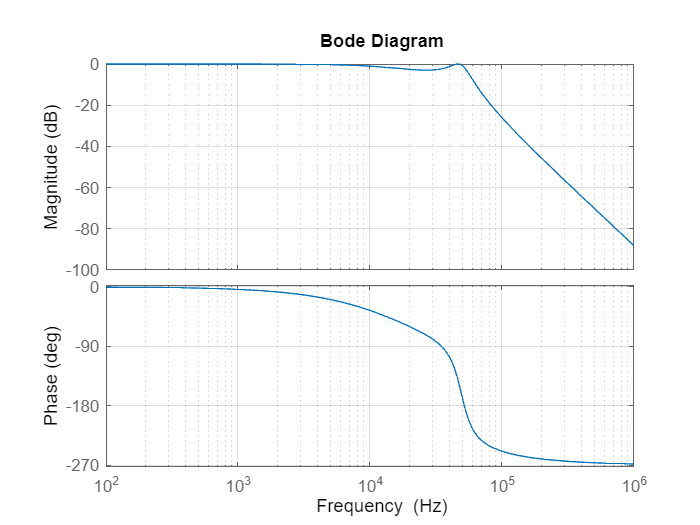


BodeDgrTP3 = bodeplot(f_von_p_TP3); 
opt = getoptions(BodeDgrTP3);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP3,opt);

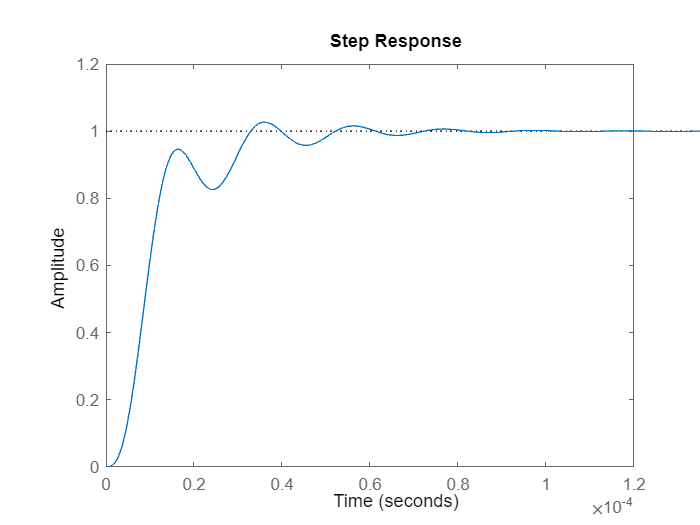


step(f_von_p_TP3);

Bode HP 1ste Ordnung

[Ziel_Coeff_Zae_HP1,Ziel_Coeff_Ne_HP1] = cheby1(1,3,fc1HP_rad,'high', 's');
Ziel_Coeff_Zae_HP1 = Ziel_Coeff_Zae_HP1 / Ziel_Coeff_Ne_HP1(2); 
Ziel_Coeff_Ne_HP1 = Ziel_Coeff_Ne_HP1 / Ziel_Coeff_Ne_HP1(2);

f_von_p_HP1 = tf(Ziel_Coeff_Zae_HP1,Ziel_Coeff_Ne_HP1)

f_von_p_HP1 =
 
    1.036e-06 s
  ---------------
  1.036e-06 s + 1
 
Continuous-time transfer function.



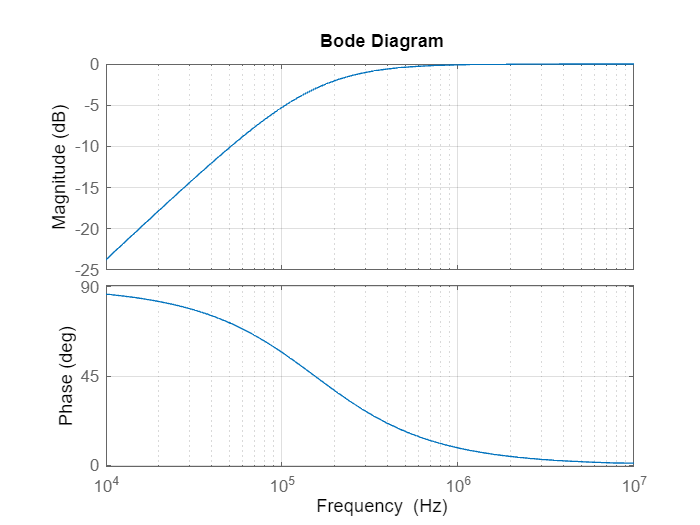


BodeDgrHP1 = bodeplot(f_von_p_HP1); 
opt = getoptions(BodeDgrHP1);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrHP1,opt);

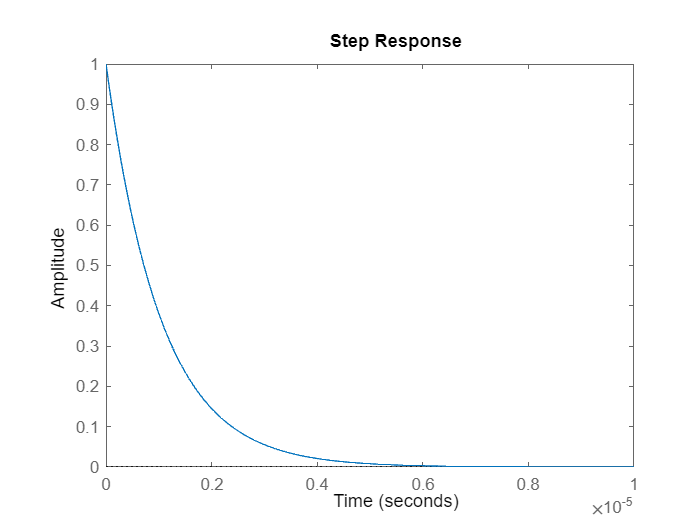


step(f_von_p_HP1); %Einschaltverhalten

Bode HP 2er Ordnung 

[Ziel_Coeff_Zae_HP2, Ziel_Coeff_Ne_HP2] = cheby1(2,3,fc2HP_rad,'high', 's');
Ziel_Coeff_Zae_HP2 = Ziel_Coeff_Zae_HP2 / Ziel_Coeff_Ne_HP2(3);
Ziel_Coeff_Ne_HP2 = Ziel_Coeff_Ne_HP2 / Ziel_Coeff_Ne_HP2(3);
f_von_p_HP2 = tf(Ziel_Coeff_Zae_HP2,Ziel_Coeff_Ne_HP2)

f_von_p_HP2 =
 
           6.1e-12 s^2
  ------------------------------
  8.616e-12 s^2 + 2.25e-06 s + 1
 
Continuous-time transfer function.



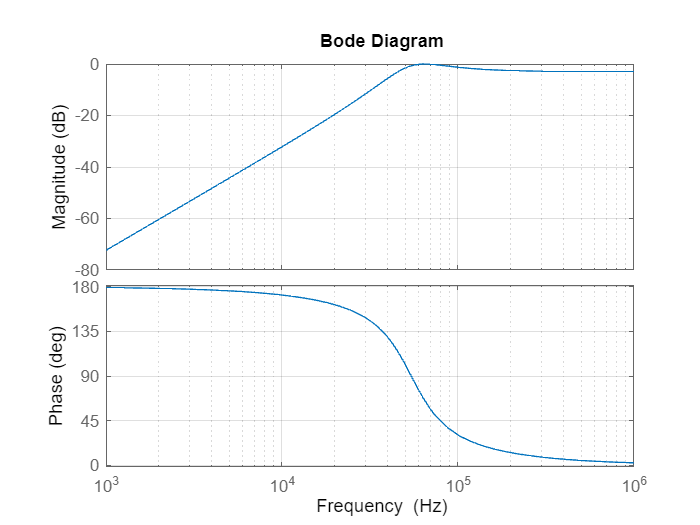


BodeDgrHP2 = bodeplot(f_von_p_HP2);
opt = getoptions(BodeDgrHP2);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrHP2,opt); 

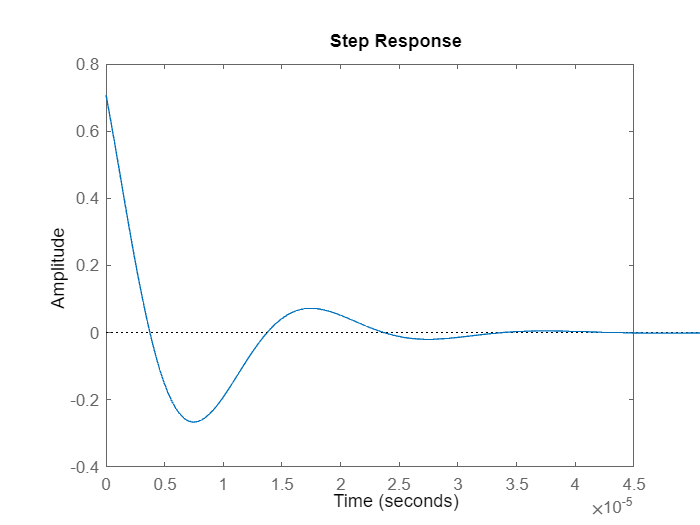


step(f_von_p_HP2);

HP3

[Ziel_Coeff_Zae_HP3, Ziel_Coeff_Ne_HP3] = cheby1(3,3,foszHP_rad,'high', 's');
Ziel_Coeff_Zae_HP3 = Ziel_Coeff_Zae_HP3 / Ziel_Coeff_Ne_HP3(4);
Ziel_Coeff_Ne_HP3 = Ziel_Coeff_Ne_HP3 / Ziel_Coeff_Ne_HP3(4);
f_von_p_HP3 = tf(Ziel_Coeff_Zae_HP3,Ziel_Coeff_Ne_HP3)

f_von_p_HP3 =
 
                   8.147e-18 s^3
  -----------------------------------------------
  8.147e-18 s^3 + 9.457e-12 s^2 + 1.906e-06 s + 1
 
Continuous-time transfer function.



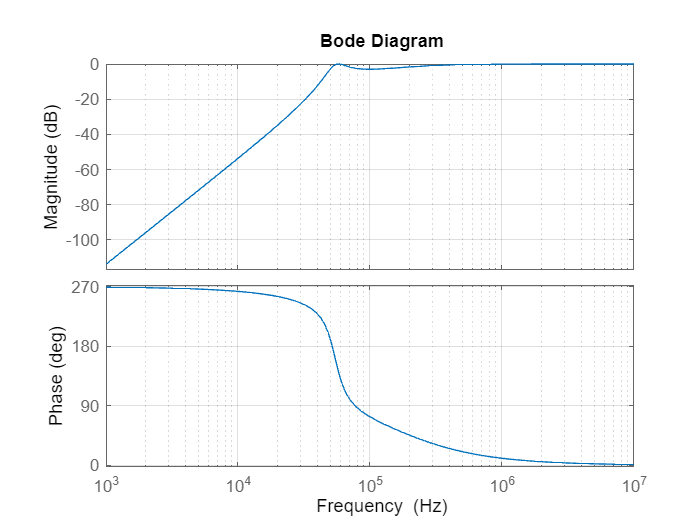


BodeDgrHP3 = bodeplot(f_von_p_HP3); 
opt = getoptions(BodeDgrHP3);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrHP3,opt);

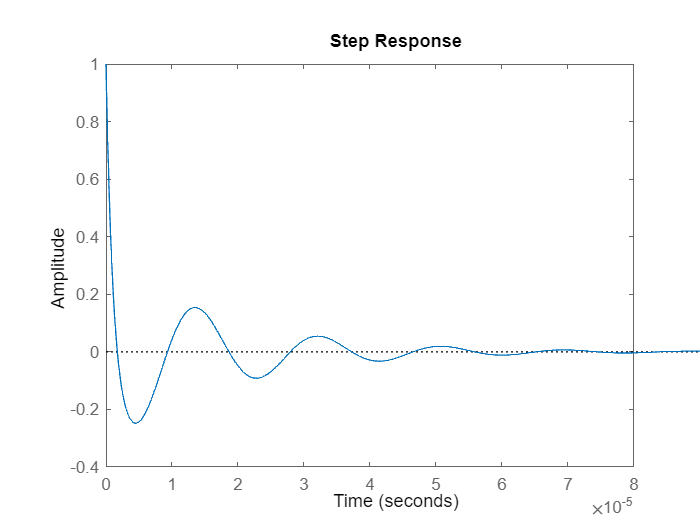


step(f_von_p_HP3);

Bode TP*HP

BP = f_von_p_TP3*f_von_p_HP3

BP =
 
                                                      
                                         8.147e-18 s^3
                                                      
  --------------------------------------------------------------------------------------------
                                                                                              
  8.437e-34 s^6 + 1.149e-27 s^5 + 4.843e-22 s^4 + 2.552e-16 s^3 + 5.125e-11 s^2 + 1.287e-05 s 
                                                                                              
                                                                                           + 1
                                                                                              
 
Continuous-time transfer function.



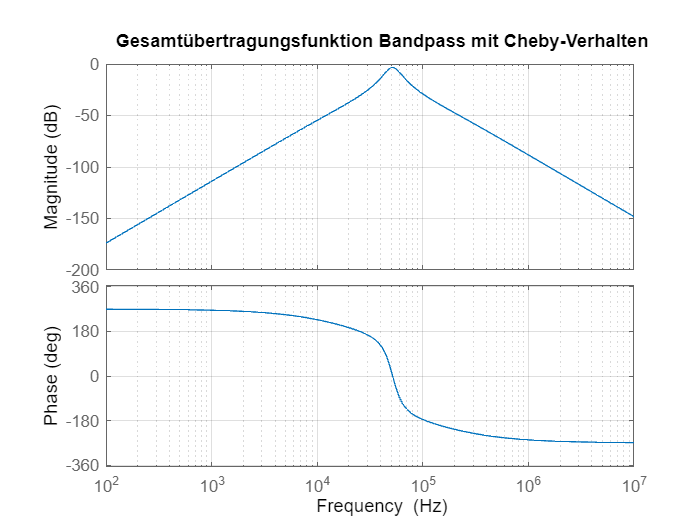

BodeDgrBP = bodeplot(BP);
title('Gesamtübertragungsfunktion Bandpass mit Cheby-Verhalten');
opt = getoptions(BodeDgrBP);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrBP,opt);

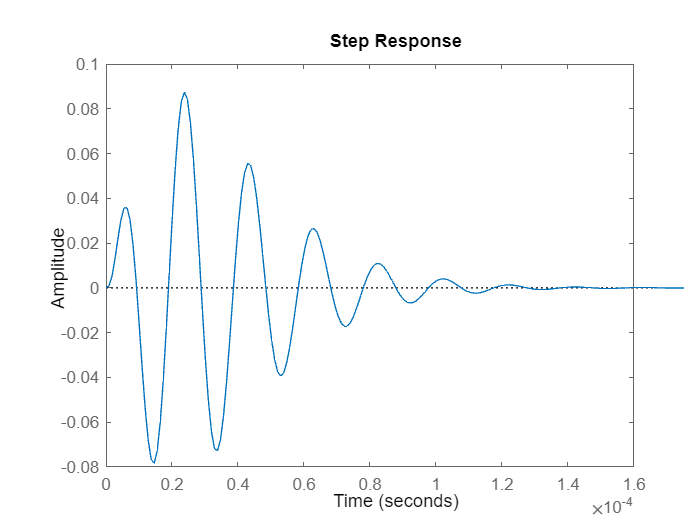

step(BP);